# Signal Quality Indicators for ECG signal

Copyright (C) 2021 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

### Acknowledgements

This notebook uses modified code written by **Hooman Sedghamiz** to compute fiducial points of the ECG signal. In addition ot uses modified ensemble averaging code from [A practical guide to wave intensity analysis](https://kparker.bg-research.cc.ic.ac.uk/guide_to_wia/03_ensemble_average.html) by **Kim H. Parker**.  

Dependencies: ecg.mat, MTEO_qrst.m, ens_averaging.m

## Introduction

In this notebook, we are going to load ECG signal that is pretty clear and show the SQI based on 3 metrics:

- Kurtosis

- Spectral power ratio

- Template waveform

The signal is sampled at 2,500 samples per second and it is of high quality.

After that we will add Gaussian noise and impulse noise to the original signal and estimate the quality. Therefore, we will consider 3 cases:

Case 1: High quality ECG signal

Case 2: ECG signal with Gaussian noise and 60 Hz noise

Case 3: Impulse noise and high SNR

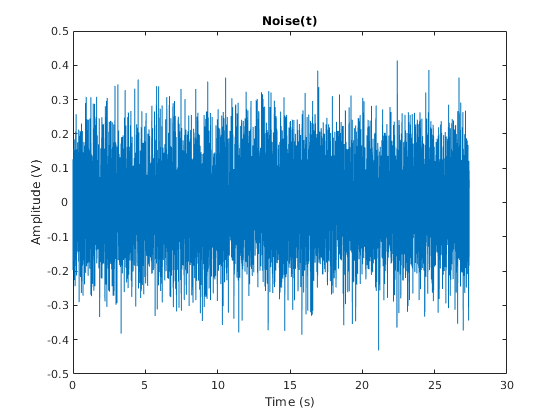

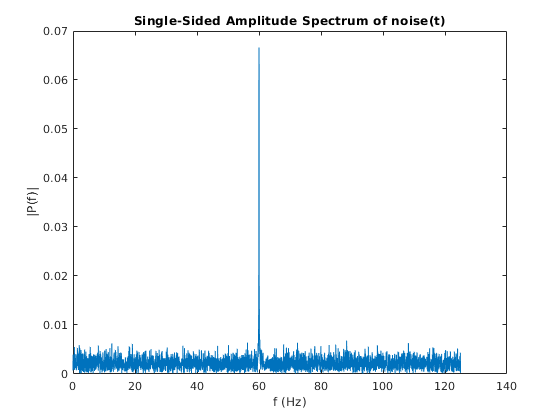

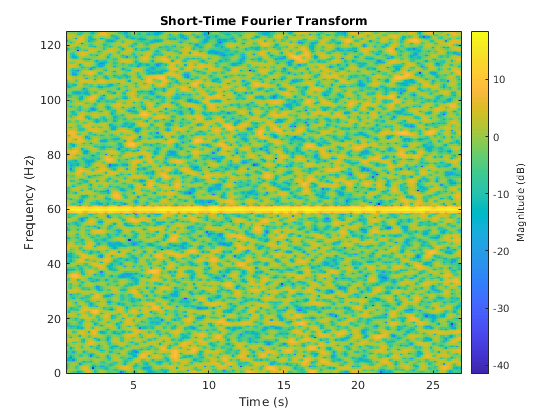

case123=3; % modify this number and run simulation for cases 1, 2 and 3
load('ecg.mat')
ratio=10;
ecg = decimate(ecg,ratio);

fs=2500/ratio;
N=length(ecg);
T=1/fs;
t = (0:N-1)*T;  

if case123 == 1

elseif case123 ==2
    noise=additive_noise_model(N, fs, 'Gaussian', [0, 0.1], '60 Hz', [0.1], 'Plotting');
    ecg=ecg+noise;
    snr(ecg,noise)
elseif case123 ==3
    noise=additive_noise_model(N, fs, 'BandLimited Impulse', [2, 1, 10], 'Gaussian', [0, 0.01],'Plotting');
    ecg=ecg+noise;
    snr(ecg,noise)
end


plot(t,ecg);
    title('Original signal with noise')
    xlabel('Time (s)')
    ylabel('Amplitude (mV)')
    

## SQI 

### Kurtosis

Let us compute the kurtosis of the signal:

kurt=kurtosis(ecg);
if kurt > 5 
    kSQI=1
else
    kSQI=0
end

kSQI = 1

### Spectral power ratio

% Define frequency ranges of interest fot the signal
Fmask_low_sig=5;
Fmask_high_sig=14;
Fmask_low_all=5;
Fmask_high_all=60;

% Compute periodogram
NyquistF = fs/2;
FResBPM = 0.5;
Nfft = (60*2*NyquistF)/FResBPM; %number of bins in power spectrum
[Pxx,F] = periodogram(ecg,hamming(length(ecg)),Nfft,fs);

% Compute power in the frequency band of the signal of interest
FMask1 = (F >= Fmask_low_sig)&(F <= Fmask_high_sig);
PowerSig = sum(Pxx(FMask1));

% Compute power in the total frequency band 
FMask2 = (F >= Fmask_low_all)&(F <= Fmask_high_all);
PowerAll = sum(Pxx(FMask2));

% Compute signal quality indices = ratio of the power in the 
PowerRatio=PowerSig/PowerAll;
if PowerRatio < 0.9 && PowerRatio > 0.5
    pSQI=1
else
    pSQI=0
end

pSQI = 1

### Template matching

Template matching includes:

- Filtering the signal

- Identifying pulses

- Extracting pulses and averaging them to obtain the template

- Calculating correlation between each pulse and the template

- Converting the correlation coefficient into a SQI score

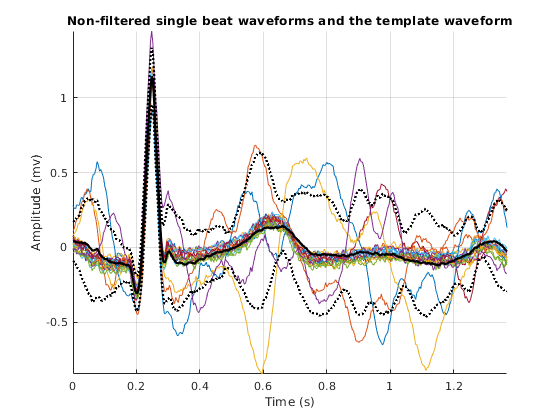

%MTEO_qrst find all characteristic waves of ECG and performs low-pass filtering with 15 Hz cut-off frequency. 
% R1(:,1) are time instances of R peaks the filtered ecg1 signal while
% R1(:,2) are th eamplitudes of the R peaks of the filtered signal ecg1.
[R1,Q,S,T_w,P_w, Te, ecg1] = MTEO_qrst(ecg,fs,0); % steps 1,2
% Ensample average of the non-filtered signal:
[pensavg, penssd, quality, r1]=ens_averaging(ecg, fs, R1(:,1), 1); % steps 3,4,5
title ('Non-filtered single beat waveforms and the template waveform')

DISPL=['No filtering, average corr coef=', num2str(mean (r1))];
disp(DISPL)

No filtering, average corr coef=0.87981


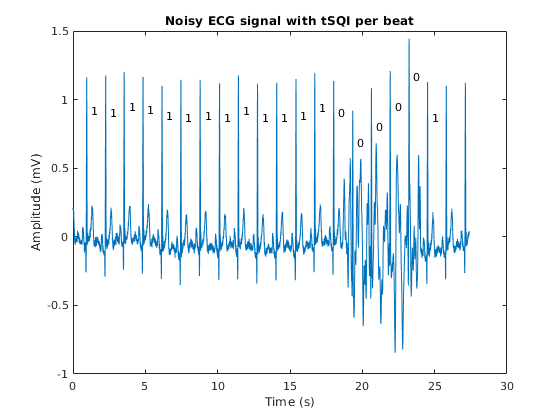

figure
plot(t,ecg)
hold on
%plot(R1(1:end-1,1)*T,R1(1:end-1,2),'o')
text(R1(1:end-1,1)*T+0.3,R1(1:end-1,2),num2str(quality))
    title('Noisy ECG signal with tSQI per beat')
    xlabel('Time (s)')
    ylabel('Amplitude (mV)')

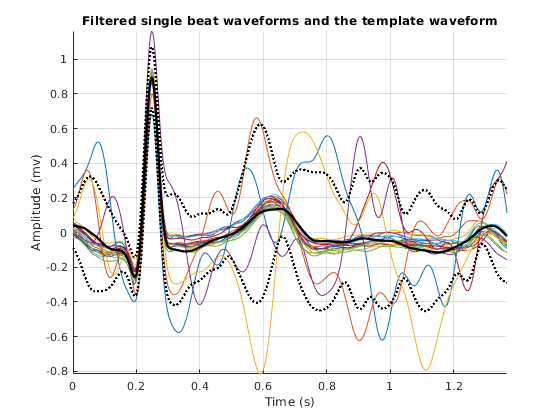

% Ensample average of the filtered signal:
[pensavg, penssd, quality,r2]=ens_averaging(ecg1, fs, R1(:,1), 1);
title ('Filtered single beat waveforms and the template waveform')

DISPL=['Bandpass filtering, average corr coef=', num2str(mean (r2))];
disp(DISPL)

Bandpass filtering, average corr coef=0.8723


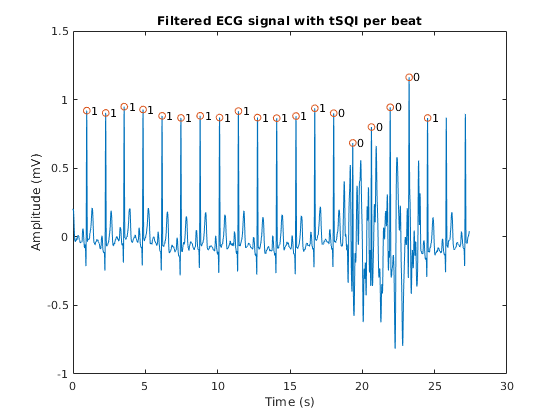

figure
plot(t,ecg1)
hold on
plot(R1(1:end-1,1)*T,R1(1:end-1,2),'o')
text(R1(1:end-1,1)*T+0.3,R1(1:end-1,2),num2str(quality))
    title('Filtered ECG signal with tSQI per beat')
    xlabel('Time (s)')
    ylabel('Amplitude (mV)')

## Exersizes

Excersize 1: repeat the analysis for cases 1, 2 and 3 and comment on the SQI indicators. Modify SNR in lines 14 and 18 to see the effect of noise on the signal quality indicators.

Excersize 2: Analyze effects of baseline drift on the quality indicators. Then filter out the baseline signal and observe the SQI again.